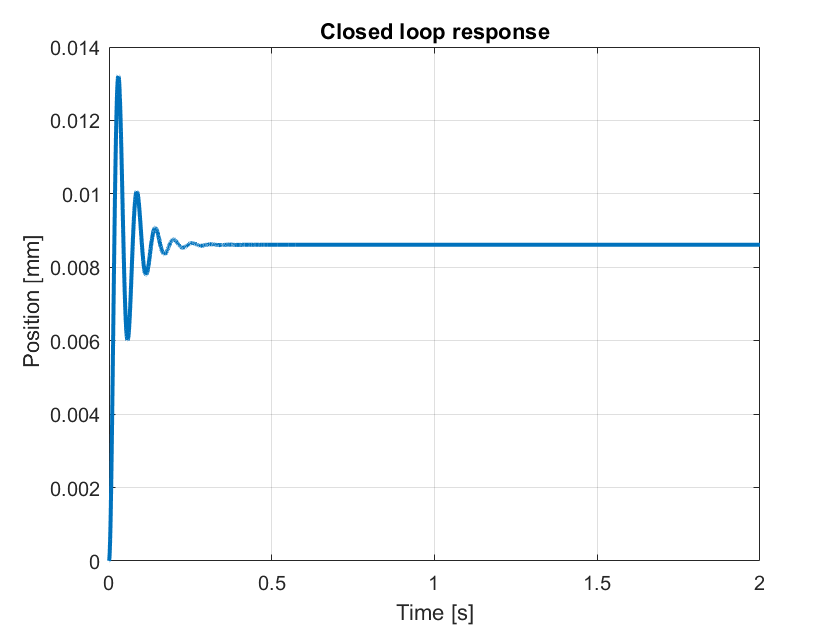

Kd = 0.0075;
Kp = 0.75;
tau = 0.0067;

actuator_gain = 0.2083;
sensor_gain = 1155.90;

v_bias = 2;
v_ref = 3.158;
K = -1.1194;
z = 100;
p = 150;

sim('MagLev_Controller_Design.slx')

% Settling at 8.6 mm [y(end)], that means intial off-set must be 5.5 mm.

figure(1); hold on; box on ; grid on;
plot(tout,yout,'LineWidth',2);
xlabel('Time [s]');
ylabel(' Position [mm]');
title('Closed loop response')